# Lab 2: Vehicle Transfer Function Model

**Learning Goals**

- Derive the transfer function of a first order system.

- Compare the transfer function and virtual vehicle responses.

- Identify the model parameters for the virtual vehicle.

While designing a controller, you typically do not use the real system. Instead, you identify a model of the system and use it to design a suitable controller. In this lab, you will construct a transfer function model of a virtual vehicle. You will validate the model and analyze how it behaves in the presence of a disturbance (driving up a hill).

## First order transfer function model

In a very simple representation, a vehicle can be modeled as a mass with two forces acting on it. The engine generates a force in the forward direction. In the opposite direction, a frictional force slows the vehicle down.

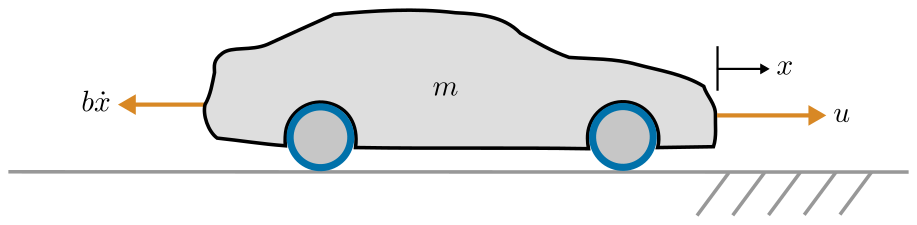

*Diagram of a simple vehicle model driving on a flat road*

In this model, the variables and parameters are:

- $x$, $\dot x$, $\ddot x$: the position (m), velocity (m/s), and acceleration (m/s$^2$) of the vehicle in the direction of travel, respectively

- $u$: traction force generated by the engine (N)

- $m$: vehicle mass (kg)

- $b$: coefficient of friction (N$\cdot$s/m)

The differential equation model is constructed using Newton's second law:

$m\ddot{x} = -b\dot{x}  + u$    (1)

The traction force is considered to be the input to the system and is therefore labeled $u$. A cruise control system attempts to determine the value of $u$ to achieve a desired response.

###  1. Derivation

In this part of the lab, you will solve for the velocity transfer function and compute the step response in MATLAB.

**Task 1**. Rewrite the equation of motion (1) in terms of the velocity, $v = \dot{x}$.

% Type your answer below as a string
task1 = "<replace this text with your answer but keep the quotes>"

**Task 2**. Compute the velocity transfer function: 


$$G(s) = \frac{V(s)}{U(s)}$$


where $U(s)$ is the Laplace transform of $u$ and $V(s)$ is the Laplace transform of the velocity $v(t)$. Use zero initial conditions.

% Type your answer below as a string
task2 = "<replace this text with your answer but keep the quotes>"

**Task 3**. Suppose that the vehicle has a mass $m = 1000$ kg and a coefficient of friction $b = 150$ N$\cdot$s/m. Define the transfer function $G$ in MATLAB using [`tf`](https://www.mathworks.com/help/control/ref/tf.html). The `tf `function has the syntax

     `tf(num,denom)`

where `num` represents the coefficients of the numerator and `denom` represents those of the denominator in descending order.

% Write your code to define G here



**Task 4**. Plot the step response for the first 60 seconds using the [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) function. The step function has the syntax

`    step(sys,Tfinal)`

where `sys` is a dynamic system (here, the transfer function `G`) and `Tfinal` is the simulation stop time.

% Write your code here



If correct, your plot should show the same curve as the one shown below.

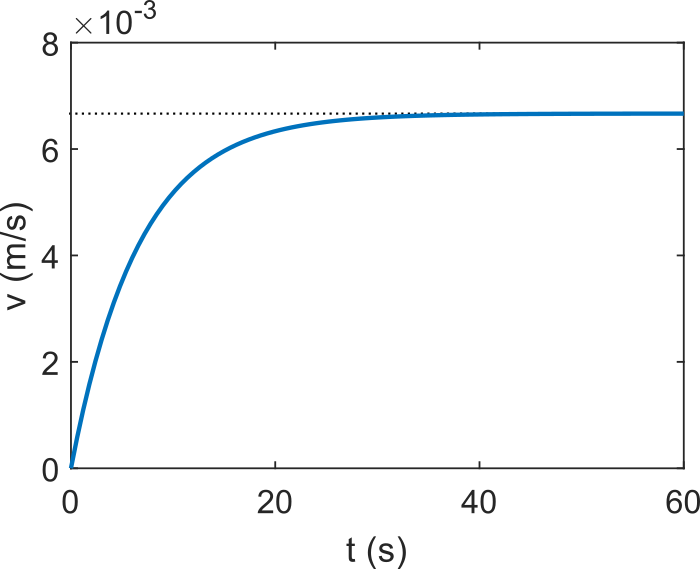

*Step response*

**Task 5**. With only a 1 N force applied to a 1000 kg vehicle, the maximum speed is very low. Increase the force applied to the vehicle to 5000 N by multiplying the transfer function by 5000. Then, recompute the step response.

**a. **What is the maximum speed achieved by the vehicle with this input in m/s?

**b. **What is the maximum speed in mph?

% Write your code here


% Record your answers to a and b here
task5a = NaN
task5b = NaN

###   2. Virtual vehicle

The velocity transfer function estimates how a vehicle will respond to variations of the input force, $u$. These may or may not match the characteristics of the vehicle under consideration. In this part, you will compare the response of the virtual vehicle to the velocity transfer function.

**Task 6**. Open the virtual vehicle model: [`VirtualVehicle.slx`](matlab: VirtualVehicle) and run it using . You should notice in the Mechanics Explorer that the vehicle doesn't move. This is because no traction force is applied to the vehicle. 

**Task 7**. Modify the Simulink model so that it computes the step response of the virtual vehicle. Add the following blocks and connect them as shown in the model diagram.

- A [Step](https://www.mathworks.com/help/simulink/slref/step.html) block with **Step time**: 0, **Initial value**: 0, **Final value**: 1, **Sample time**: 0.

- A [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the velocity $v$ (the output port `vd` of the virtual vehicle shows the speed in the direction of travel).

- Double-click the vehicle image to open the virtual vehicle dialog parameters. Set the **Traction force saturation limit **to **14800** and the **Disturbance type** to **none**.

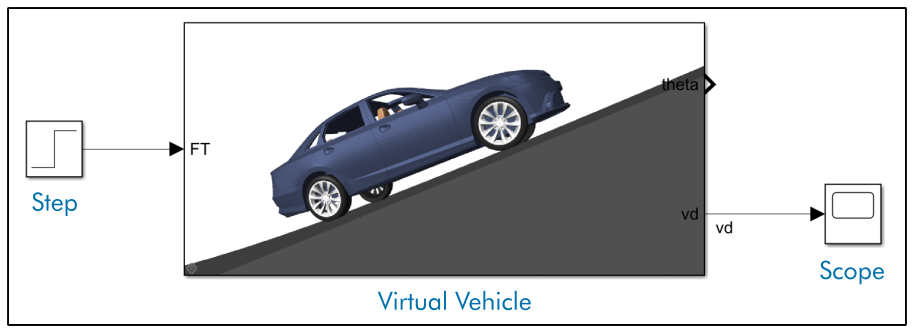

*Simulink model that computes the virtual vehicle's response to a 1 N step input.*

**Task 8**. Run the model using . The vehicle may not appear to move (it should move, but very slowly), because only a 1 N force is applied by a step input. Double-click the scope to view the velocity. If correct, the output of the scope should appear as shown below. 

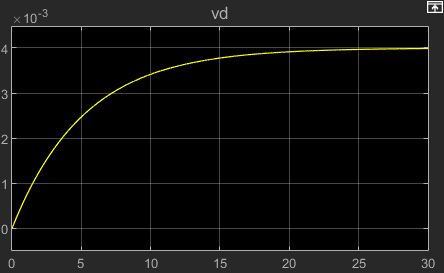

*Scope output rescaled using *

 **Pro-tip**: You can measure values in the scope using **Cursor Measurements**. From the Scope menu, select **Tools **> **Measurements **> **Cursor measurements. **Select and drag the vertical lines to change the measurement location.

    **a.** What is the maximum speed reached in m/s (the default unit of the vehicle model)? For this exercise, it is acceptable if you use the maximum value after 30 seconds.

% Type your answer below
task8a = NaN

**    b. **For a first order system, the time constant $\tau$ is defined as the amount of time it takes to reach 63% of the final value.  What is the time constant of the virtual vehicle? Use the cursor measurement to identify the value from the scope. Using the cursor will not provide the exact answer, but the value estimated using the cursor is acceptable.

**Hint: **Ensure the step time on the Step block is zero.

% Type your answer below
task8b = NaN

**Task 9**. Add a [Transfer Fcn](https://www.mathworks.com/help/simulink/slref/transferfcn.html) block with the numerator and denominator set to match the transfer function you defined in the previous part of this lab (double click the Transfer Fcn block to adjust its parameters). Then, connect it to the model as shown below.

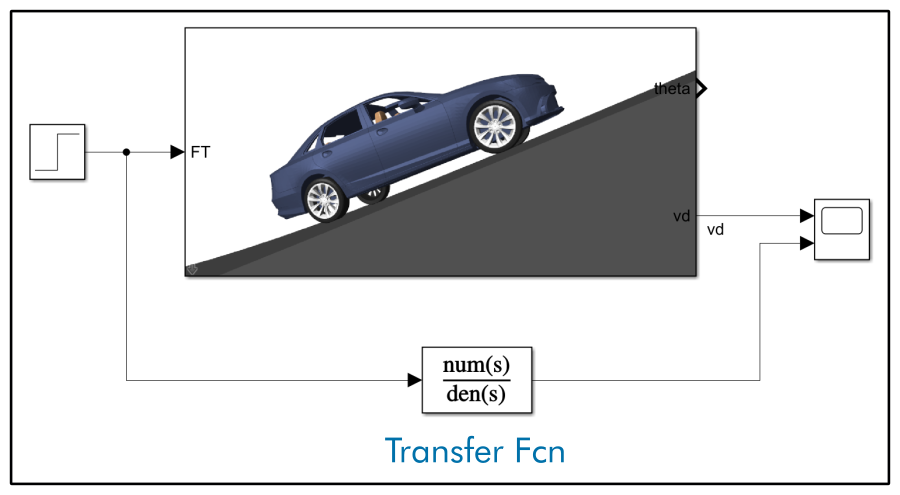

*Simulink model that computes the virtual vehicle and the velocity transfer function step response simultaneously*

Run the model and observe the velocity comparison in the scope. The plot below shows the correct scope output.

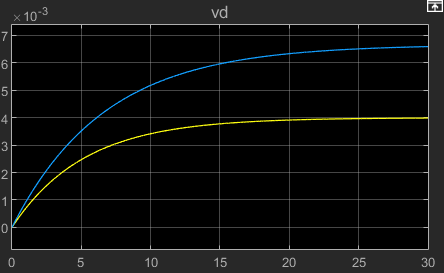

*Scope result*

 **Pro-tip**: You can add a legend to the plot. From the Scope menu, select **View** > **Legend**.

**a.** Does the virtual vehicle appear to have the step response of a first order system?

task9a = "-"

**b.** Do the models share the same time constant?

task9b = "-"

**c.** Do the models approach the same final velocity?

task9c = "-"

###  3. System identification

In the previous part of the lab, you compared the step responses of the transfer function model and the virtual vehicle. The responses were similar, but the systems clearly had different parameters. In this part, you will identify the transfer function parameters that model the virtual vehicle using the step response.

**First order transfer function time constant**

A first order transfer function can be written in terms of its limiting value $h_\infty$ and time constant $\tau$ (the time taken to reach 63% of the limiting value). 


$$H(s) = \frac{h_\infty }{\tau s + 1}$$


You can analytically compute the transfer function step response of $H$ to be:


$$h(t) = h_\infty(1 - e^{-t /\tau})$$


From the step response it is easy to show that 

- $\lim_{t \rightarrow \infty} h(t) = h_\infty$ and 

- $h(\tau) = h_\infty(1 - e^{-1})  \approx 0.632 h_\infty$.

These two properties show that $h_\infty$ is the limiting value of the step response and $\tau$ is the time required to reach 63% of the limiting value.

**Task 10. **Use the data you recorded in **Task 8** to derive the first order transfer function $H$ using the limiting value and the time constant. You should plug your estimated values for $h_\infty$ and $\tau$ into the definition of $H$. Define the transfer function in MATLAB using [`tf`](https://www.mathworks.com/help/control/ref/tf.html) and compute the step response using the [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) function. Does the result match the step response of the virtual vehicle?

% Write your code here



**Task 11. **The first principles derived velocity transfer function is


$$G = \frac{1 }{ms + b}$$


Use the fitted model $H$ you derived in **Task 10** to identify 

**a. **the virtual vehicle's mass $m$ 

**b.** friction coefficient $b$.

**Hint: **set $G$ equal to $H$ and then solve for $m$ and $b$.

% Compute m here
task11_m = NaN
% Compute b here
task11_b = NaN

**Task 12. **Adjust the transfer function block in the Simulink model to use the values of $m$ and $b$ identified in **Task 11**. Run the model. Does the step response of the velocity transfer function match the virtual vehicle's?

task12 = "-";

**Task 13. **Add a [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) block after the Step block as shown in the diagram below.

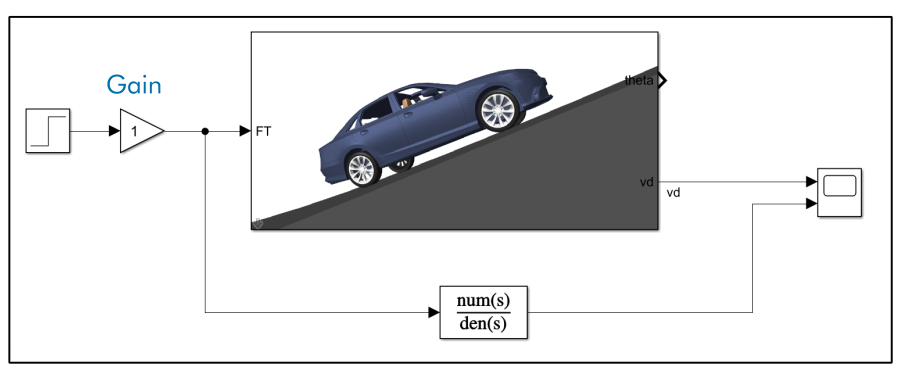

*Model diagram with a gain block*

**a. **Increase the gain to 10. Does the transfer function model still match the virtual vehicle response?

task13a = "-"

**b. **Increase the gain to 5000. Does the transfer function model match the virtual vehicle response?

task13b = "-"

As demonstrated in Task 13, the transfer function models the virtual vehicle well for small inputs, but for larger inputs becomes less accurate. This happens because the transfer function is linear, while the more realistic virtual vehicle's response is nonlinear. 

**Task 14.** In this task, you will continue to explore the differences between the transfer function and virtual vehicle responses.

**a. **What should the step input be multiplied by for the velocity transfer function to reach a top speed of 50 mph = 22.4 m/s? Verify your answer by adjusting the gain to this value and running the model.

**Hint: **the transfer function is linear, so if you multiply the input by a value, the output will be multiplied by the same value.

task14a = NaN

**b. **With the gain set to the values you found in part **a **of this task, what is the top speed of the virtual vehicle in mph? (Hint: use the Cursor Measurement tool to obtain the value in m/s and convert to mph)

task14b = NaN 

**c. **Is the transfer function model derived in this lab the best linear model for constructing a cruise control algorithm? Why or why not?

task13c = "<replace this text with your answer but keep the quotes>"